# Fundamentos de Matlab: Sesión 4

## Función Anómina: 

Otra forma de definir funciones en Matlab es utilizar el símbolo **@, **Este comando permite definir una función en un script y utilizarla en la consola de comandos. Para implementarla basta con poner el símbolo "@" y, después, entre paréntesis, los argumentos que toma la función. Por último, se agrega la forma funcional que se desee.

 A continuación, se muestra cómo realizar este proceso mediante un ejemplo:

Se quiere implementar la siguiente función:


$$F\left(x\right)=3x^3 -x\;\sin \left(x\right)$$


Fx= @(x) (3*x.^3 - sin(x).*x)

Fx = function_handle with value:
    @(x)(3*x.^3-sin(x).*x)

La forma en la que está definida la función permite que el argumento de entrada sea un escalar o un arreglo, para probarla podemos definir un vector equiespaciado entre 0 y 2 de 201 valores, luego una matriz cuadrada de 6X6 y por último escalar y pasarlos como argumentos a la función anónima declarada, 

veamos:

t=0:pi/100:2*pi;
A=  magic(6); 
x = 10;
Vect = Fx(t)  %  Función anónima Fx con Vector como parámetro

Vect =             0  -8.9378e-04  -3.2011e-03  -6.3580e-03  -9.7966e-03  -1.2945e-02  -1.5228e-02  -1.6067e-02  -1.4877e-02  -1.1072e-02  -4.0617e-03   6.7486e-03   2.1957e-02   4.2164e-02   6.7976e-02   1.0000e-01   1.3885e-01   1.8514e-01   2.3948e-01   3.0251e-01   3.7483e-01   4.5709e-01   5.4991e-01   6.5392e-01   7.6976e-01   8.9806e-01   1.0395e+00   1.1946e+00   1.3642e+00   1.5488e+00   1.7490e+00   1.9656e+00   2.1992e+00   2.4505e+00   2.7200e+00   3.0085e+00   3.3166e+00   3.6449e+00   3.9942e+00   4.3650e+00   4.7581e+00   5.1740e+00   5.6136e+00   6.0773e+00   6.5659e+00   7.0800e+00   7.6203e+00   8.1875e+00   8.7821e+00   9.4050e+00


Mat= Fx(A)    %  Función anónima Fx con Matriz como parámetro

Mat =    1.2864e+05   2.1585e+00   6.4968e+02   5.2708e+04   2.0574e+04   4.1494e+04
   8.0577e+01   9.8286e+04   1.0244e+03   2.7765e+04   3.6520e+04   4.6878e+04
   8.9386e+04   2.1833e+03   2.2181e+01   3.1944e+04   5.9023e+04   2.3982e+04
   1.5281e+03   6.5848e+04   1.0778e+05   1.4755e+04   3.0054e+03   1.0115e+04
   8.1030e+04   3.7979e+02   1.1789e+05   5.1904e+03   8.2181e+03   1.2293e+04
   1.9503e+02   1.4000e+05   7.3186e+04   6.5855e+03   1.7510e+04   4.0040e+03


Sc= Fx(x)     %  Función anónima Fx con escalar como parámetro

Sc =    3.0054e+03

### Funciones anónimas anidadas:

Una función anónima puede recibir otra función como parámetro, puede ser una función propia Matlab, funciones de usuario u otra función anónima:

Para comprender mejor esta situación se explicará primero como trabaja la función *"integral*" de Matlab: La sintaxis de esta función es : 

devuelve la integral definida de la función *FUN* entre los límites inferior (*lim_inf)*y superior  (*lim_sup).*  *FUN *debe ser una función anónima.

veamos un ejemplo, evaluar la siguiente integral:


$$F(h) =  \int_{0}^{3} 2 h^2 + h \, \cdot \delta h$$


el comando a ejecutar será:

Fh= integral(@(h) (2*h.^2 + h) ,0,3)

Fh =    2.2500e+01

También se puede definir antes la función a integrar como una función anónima y pasarla como argumento, así:

gx = @(h) (2*h.^2 + h)

gx = function_handle with value:
    @(h)(2*h.^2+h)

Fh2 = integral(gx , 0,3)

Fh2 =    2.2500e+01

**Ejemplo práctico:**


$$F(h_2O) = \rho \cdot g \cdot L \, \cdot \int_{0}^{h}  h \, \cdot \delta h$$


La expresión anterior corresponde a la función de la fuerza ejercida por el agua sobre una de las paredes de un tanque: Aquí:

- L es la longitud de la pared

- $\rho$ es la densidad del agua 

- g es la aceleración de la gravedad

- h es la altura del agua.

clear 
L= 100      %   Longitud de la pared

L =    100

h = 25      %   altura del agua

h =     25

g = 9.81    %   aceleración de la gravedad

g =    9.8100e+00

rho = 1000  %   densidad del agua

rho =         1000

Fh = @(h,L) (rho*g*L*(integral(@(c) c,0,h)))

Fh = function_handle with value:
    @(h,L)(rho*g*L*(integral(@(c)c,0,h)))

Fuerza = Fh (h,L)  % Fuerza en Newton

Fuerza =    306562500

Algunas de las funciones propias de Matlab tienen una versión alterna que recibe como  parámetro adicional una función anónima, se reconocen porque el nombre de la funcíón comienza por la letra ***"f"***. Las funciones **"plot()"**  y *** "fplot()"*** son un ejemplo de esto.

## Gráficos en Matlab:

Las gráficas son un excelente complemento para las funciones ya que permiten observar el comportamiento de las variables y en general de un sistema o de una parte de él. La función para graficar más conocida de Matlab es la función **"plot ()", **pero existen otras varias que nos ayudan a presentar gráficos de múltiples formas. Dependiendo del contenido y la forma que se quiera mostrar Matlab clasifica las funciones para gráficos en 11 categorías:

- **Gráficas de líneas: **plot(), plot3(),stairs(),.. otras

- **Gráficas de distribución de datos:** histogram(), pie(), scatter(), ... otras

- **Gráficas de datos discretos**: bar(), barh(), stem(), pareto(), ...otras

- **Gráficas geográficas**: geobubble (), geoplot() y geoscatter().

- **Gráficas polares:** polarplot(), compass(), ezpolar(), ... otras

- **Diagramas de contorno:** contour(), contourf(), contour3(), ... otras

- **Gráficas de campos vectoriales: **quiver(), quiver3() y feather().

- **Gráficas de superficie de malla:** surf(), sufc(), ribbon(), ... otras

- **Visualización de volúmenes:** streamline(), coneplot(), streamlice(), ... otras

- **Animaciones:** animatedline(), comet() y comet3().

- **Imagénes:** image() e imagesc().

### Funciones básicas para Graficar:

Antes de empezar a graficar es necesario saber que en Matlab se puede presentar una o varias gráficas en una sola ventana, cada vez que se crea una gráfica por medio de cualquier  función se sobre escribe la gráfica anterior. Por defecto la primera ventana de gráfica se crea con el nombre "Figure 1". Si se quiere que Matlab abra una ventana diferente para cada gráfica se debe nombrar ésta antes de usar la función que realiza la gráfica, para ello se hace uso del comando ***"figure(n)"***, dónde "n" indíca el número de la ventana en la que se va a crear la gráfica, si la ventana ya ha sido creada se sobre escribirá la gráfica existente.

#### Función  plot() 

La función plot (x,y) crea un gráfico de líneas en dos dimensiones que representa en un plano cartesiano los valores de*"y"* en función de los valores de* "x". La función *plot() puede recibir uno o varios argumentos, siendo uno el número de argumentos, plot () devuelve la gráfica de los valores contenidos en el arreglo pasado como argumento en función de sus índices. 

Ejemplo 1.  plot(v)

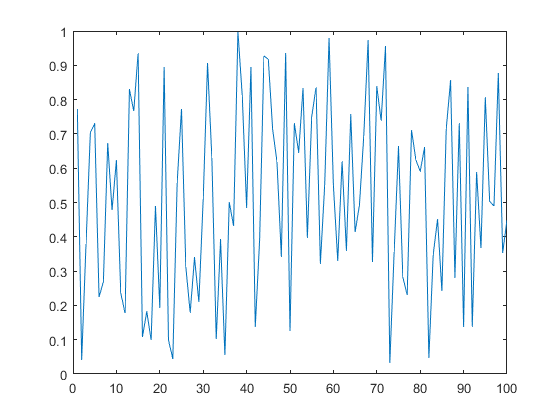

v = rand(1,100);  % vector de números aleatorios 1X100
figure(1)
plot(v)           % grafíca en el eje "x" los indices del vector,en el eje "y" los valores de v           

Ejemplo 2: plot (t,y)


figure(2)
t = -pi:pi/100:pi;
x = cos(t).*-exp(-0.5*t) 

x =    4.8105e+00   4.7332e+00   4.6525e+00   4.5687e+00   4.4819e+00   4.3924e+00   4.3003e+00   4.2058e+00   4.1091e+00   4.0105e+00   3.9100e+00   3.8079e+00   3.7043e+00   3.5994e+00   3.4934e+00   3.3864e+00   3.2786e+00   3.1702e+00   3.0613e+00   2.9520e+00   2.8426e+00   2.7330e+00   2.6235e+00   2.5143e+00   2.4053e+00   2.2968e+00   2.1889e+00   2.0816e+00   1.9752e+00   1.8696e+00   1.7650e+00   1.6615e+00   1.5592e+00   1.4582e+00   1.3585e+00   1.2603e+00   1.1635e+00   1.0684e+00   9.7488e-01   8.8308e-01   7.9304e-01   7.0483e-01   6.1848e-01   5.3406e-01   4.5160e-01   3.7114e-01   2.9272e-01   2.1637e-01   1.4211e-01   6.9983e-02


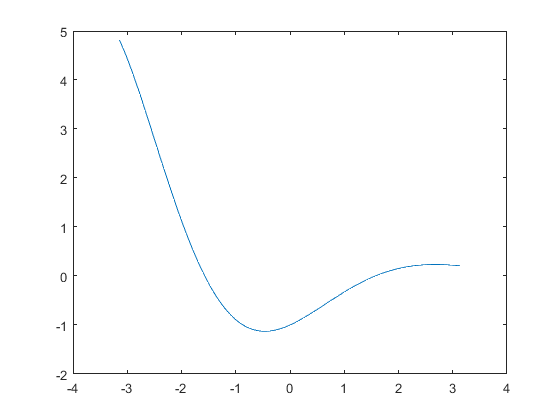

figure(2)
plot (t,x)

#### Funciones **title()** **xlabel()**, **ylabel()** y zlabel()

Establecen el título y las etiquetas para cada uno de los ejes.

Ejemplo 4: Titule y etiquete los ejes de la figura anterior.

title ('Gráfica de un vector')
xlabel ('indices del vector')
ylabel ('valoes en el vector')
title('f(x) = cos(t).*-exp(-0.5*t)')
xlabel ('t')
ylabel('f(t)')

#### Líneas de cuadrícula:

Matlab dispone de una grilla o cuadrícula que le ayudará a ubicar punto en una gráfica para activarla o desactivarla se usan las funciones ***grid on()*** y ***grid off()***, respectivamente. La función "grid minor " hace una cuadricula más pequeña.

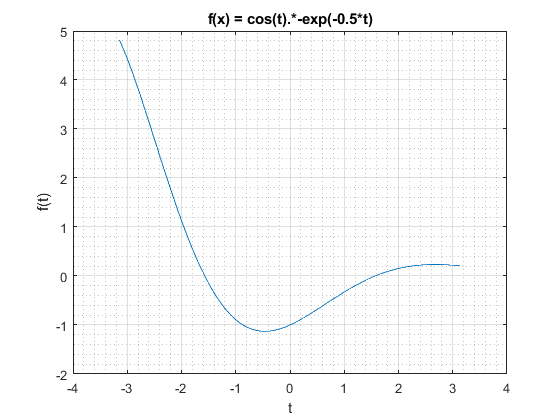

grid on
grid minor

#### Funcion subplot()

Para organizar varias gráficas en una sola ventana se hace uso del comando ***"subplot()" ,*** éste comando recibe como parámetros un vector, *"subplot(n,m,p)"* crea un arreglo de gráficas de orden *"n X m"* y convierte los ejes actuales en los ejes de la figura "p" . Para destacar que  Matlab ordena los gráficos por filas y no por columnas como lo hace con las variables y los arreglos en memoria.

Ejemplo 3. subplot(n,m,d)

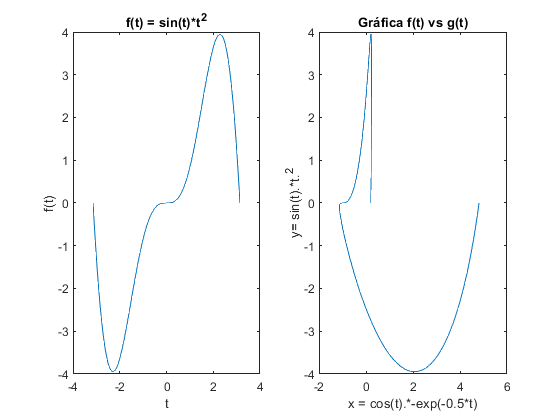

figure(3)
y= sin(t).*t.^2;   % fugura 3-1
subplot(1,2,1)
plot(t,y)           % figura 3-2
title ('f(t) = sin(t)*t^2')
xlabel('t')
ylabel  ('f(t)')
subplot(1,2,2)
plot (x,y)
title ('Gráfica f(t) vs g(t)')
xlabel('x = cos(t).*-exp(-0.5*t)')    % La gráfica muestra esta función en el eje x
ylabel  ('y= sin(t).*t.^2')  % La gráfica muestra esta función en ele eje y

#### Función axis()

Al momento de graficar es importante tener en cuenta el rango de datos y los limites o intervalos de datos que se quiere analizar, para manipular los valores de los ejes Matlab cuenta con la función ***"axis()"***

- ***axis(): ***Esta función puede recibir como argumentos un vector de 4 o de 6 elementos según se trate de gráficas en 2D *(xmin,max,ymin,ymax) *o de gráficas en 3D *(xmin,max,ymin,ymax,zmin,zmax), *o un vector de 8 elementos si se quiere establecer el valor inicial  y final del mapa de colores, del cual se hablará más adelante*.*

*Ejemplo: *

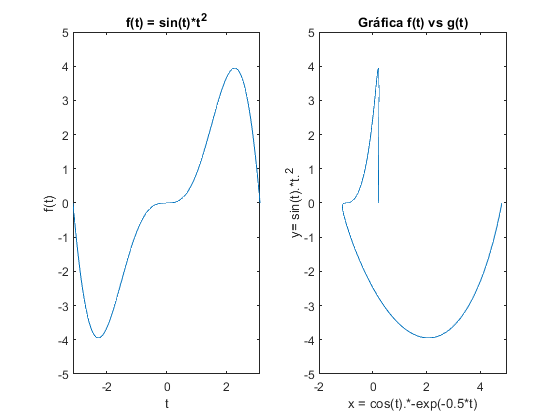

subplot(1,2,1)
axis([-pi,pi,-5,5])
subplot(1,2,2)
axis([-2,5,-5,5])
title ('Gráfica f(t) vs g(t)')
xlabel('x = cos(t).*-exp(-0.5*t)')    % La gráfica muestra esta función en el eje x
ylabel  ('y= sin(t).*t.^2')           % La gráfica muestra esta fuinción en ele eje y

-  ***xlim(),  ylim()***   Establecen los limites solo para los ejes x, y respectivamente.

#### **Use "ticks" para dar formato a los ejes de una gráfica:**

Los ticks son las pequeñas líneas que se muestran sobre los ejes en una gráfica, para conocer y/o modificar las propiedades de los ticks en el eje de una gráfica se suelen  emplear varias funciones:

- `n`***ticks() :***  Reemplace   "n"   por** x,y,**o **z** para establecer los valores de los ticks en los ejes *x,y o z* , el argumento de la función es un vector con los valores crecientes de los ticks.

- n**tickangle(**$\alpha$**): **También en los eventos en los que no sea posible observar claramente los valores puede mostrar los valores de los ticks con una inclinacion en un  ángulo determinado. use n**tickangle(**$\alpha$**). **El ángulo lo define $\alpha \;$y dbe ser representado en grados.

Ejemplo 5: Cree una nueva figura con un arreglo de 1 X 2 y en la primera gráfica trace la función $f(t)=sin(t)*t^2$ entre - pi y pi. y muestre en el eje x los valores para -pi, -3pi/4,-pi/2,-pi/4 0, pi/2, pi/4,3pi/4, pi  

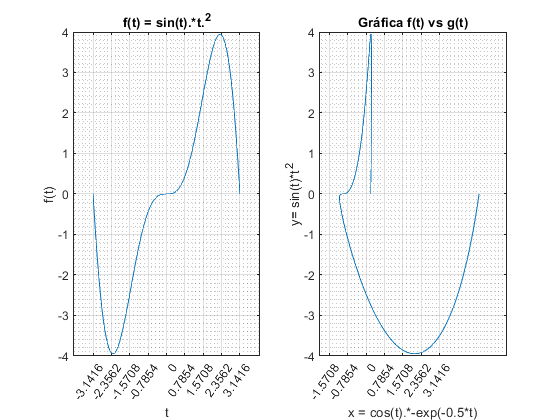


figure(4)

subplot(1,2,1)
y = sin(t).*t.^2;
plot (t,y)
title ('f(t) = sin(t).*t.^2')
xlabel('t')
ylabel  ('f(t)')
val_ticks =-pi:pi/4:pi;
xticks (val_ticks)
xtickangle(55)
grid on
grid minor

subplot(1,2,2)
plot (x,y)
title ('Gráfica f(t) vs g(t)')
xlabel('x = cos(t).*-exp(-0.5*t)')    % La gráfica muestra esta función en el eje x
ylabel  ('y= sin(t)*t^2')           % La gráfica muestra esta fuinción en ele eje y
val_ticks =-pi:pi/4:pi;
xticks (val_ticks)
xtickangle(55)
grid on
grid minor

- n**ticklabels: **Para casos en los que se quiera establecer etiquetas en vez de valores en los ticks  de un eje específico de una gráfica:

Ejemplo 6:  Cree una nueva gráfica con los mismos datos de la gráfica anterior y cambie los valores de los ticks a etiquetas en términos de  $\pi$

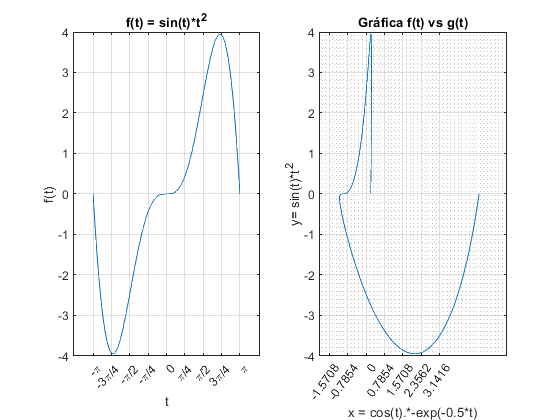

hold off
subplot(1,2,1)
plot (t,y)
title ('f(t) = sin(t)*t^2')
xlabel('t')
ylabel  ('f(t)')
grid on
val_ticks =-pi:pi/4:pi;
xticks (val_ticks);
xticklabels ({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})
xtickangle(45)

#### Funciones hold on hold off

Si lo que se quiere es dibujar varias curvas en una sola gráfica, la función "hold on" retiene lo pintado en los ejes actuales para que no se elimine la gráfica existente al momento de pintar una nueva. La funcion "hold off" elimina los datos de la gráfica existente antes de pintar una nueva.

Ejemplo 8

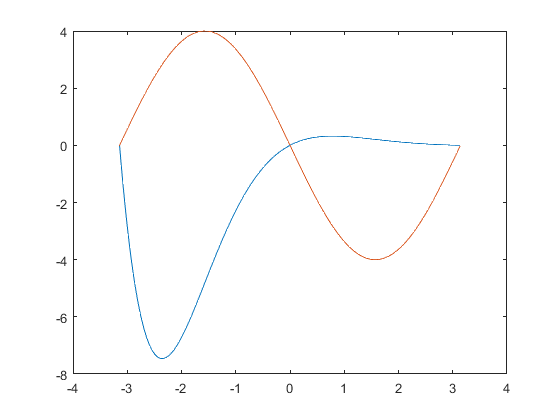

figure (5)
y = exp(-1.*t).*sin(t);
plot (t,y)
hold on
y1=-4*sin(t);
plot(t,y1)

La función *plot()* también puede pintar varias funciones en un solo gráfico si el argumento de la variable en el eje *"y" *es un arreglo con las funciones a graficar, es necesario que todas las expresiones en el arreglo sean función de la variable en el eje x.

Ejemplo 9

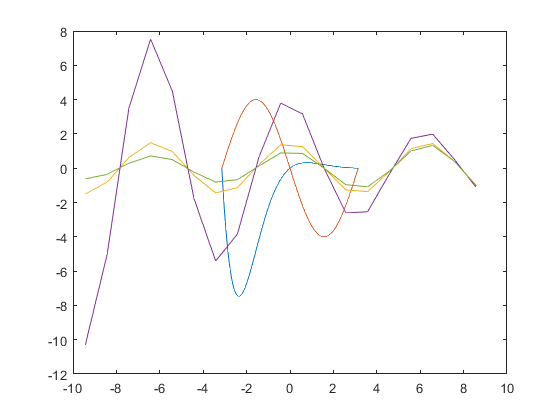

figure(6)
x = -3*pi:3*pi;
y = [1.5*cos(x); 4*exp(-.1*x).*cos(x); exp(.05*x).*cos(x)]';
figure(5)
plot(x,y);

Para mostrar en la gráfica actual una etiqueta que indique los datos que representa cada grafica se usa la función "legend()"

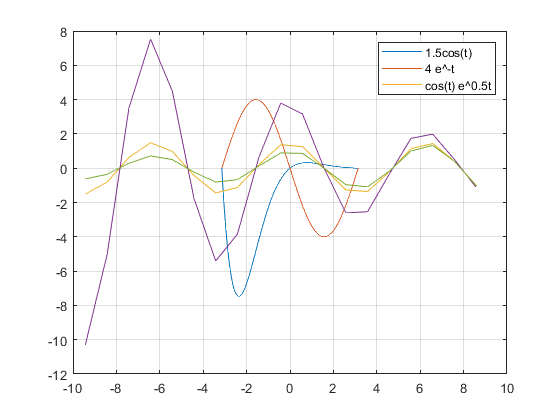

legend ('1.5cos(t)','4 e\^-t','cos(t) e\^{0.5t} ')
grid on

**Nota: **el uso de los comandos; grid on, grid off, hold on hold off, legend y los comandos para formatear los ticks se reestablecen a su valor por defecto al crear una nueva gráfica.

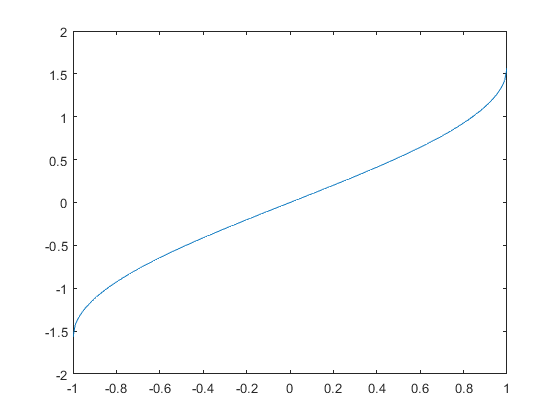

figure(7)
r= -1:0.01:1;
y1 = asin(r);
plot(r,y1)

#### Función plot3():

La función plot3(x,y,z) de Matlab permite hacer gráficos de líneas en tres dimensiones sobre el espacio de los ejes x,y,z. en dónde la altura de la gráfica en los ejes $x,\, y$ está representada en el eje  *z*

Ejemplo:

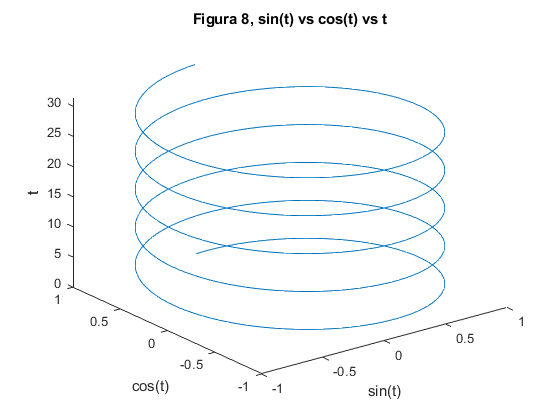

figure(8)
t = 0:pi/50:10*pi;
st = sin(t);
ct = cos(t);
plot3(st,ct,t)
title ('Figura 8, sin(t) vs cos(t) vs t')
ylabel ('cos(t)')
xlabel ('sin(t)')
zlabel ('t')

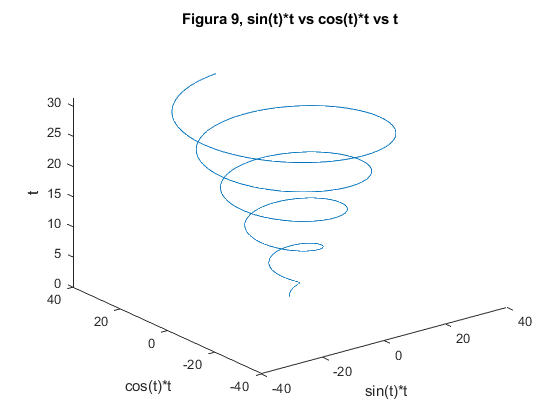

figure(9)
st = sin(t).*t;
ct = cos(t).*t;
plot3(st,ct,t)
title (['Figura 9, sin(t)*t vs cos(t)' ...
    '*t vs t'])
ylabel ('cos(t)*t')
xlabel ('sin(t)*t')
zlabel ('t')

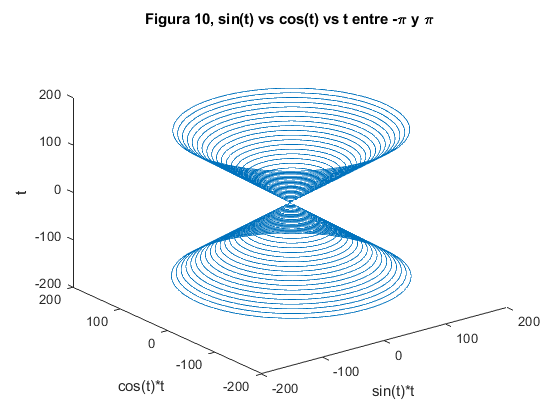

figure (10)
t = -50*pi:pi/100:50*pi;
st = sin(t).*t;
ct = -cos(t).*t;
plot3(ct,st,t)
title ('Figura 10, sin(t) vs cos(t) vs t entre -\pi y \pi')
ylabel ('cos(t)*t')
xlabel ('sin(t)*t')
zlabel ('t')

La función **peaks()** es una función de dos variables usada en la demostración de otras funciones gráficas como *surf, colormap*, entre otras:

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


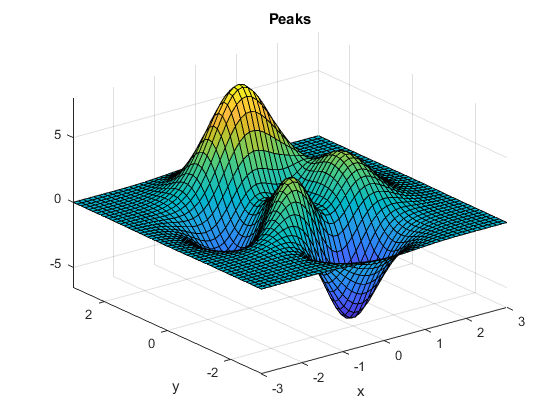

peaks()

#### Gráficas Polares

Matlab puede graficar en coordenadas polares, la función ***polarplot(***$\theta$***,r)*** genera una gráfica en coordenadas polares del ángulo $\theta$ (en radianes) y la distancia radial r:

Ejemplos:  

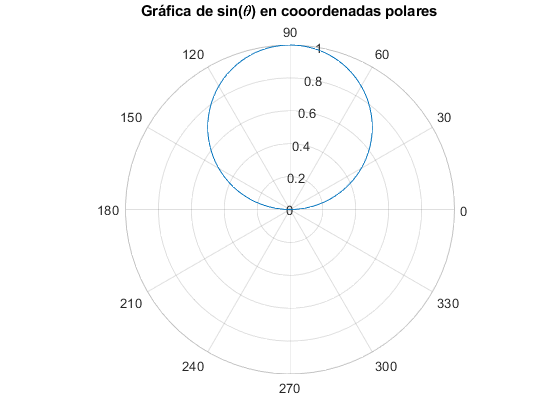

clear all   
close all   % cierra todas las ventanas de graficas abiertas
theta = 0:pi/100:pi;
yp= sin(theta);
figure(1)
polarplot(theta,yp)
title('Gráfica de sin(\theta) en cooordenadas polares')

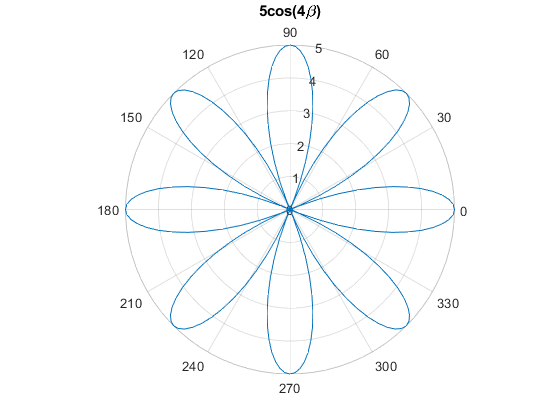


figure(2)
beta = 0:0.01*pi:2*pi;
r = 5*cos(4*beta);
polarplot (beta,r)
title('5cos(4\beta)')

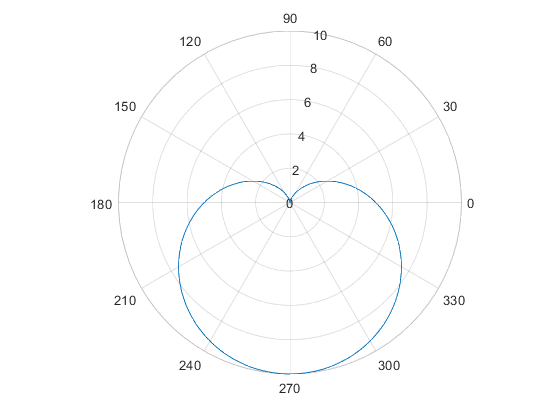


figure(3)
r2= 5-5*sin(beta);
polarplot(beta,r2)

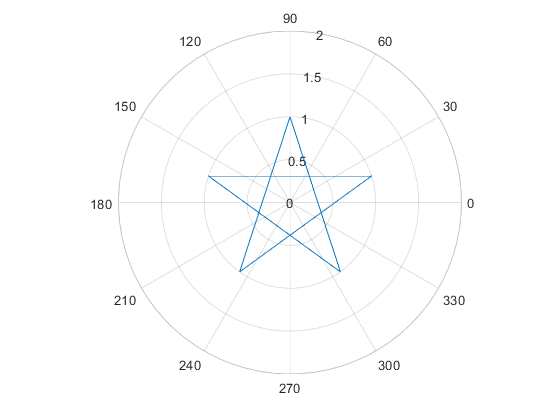


figure(4)
theta2 = pi/2:4/5*pi:4.8*pi;
r3= ones(1,6);
polarplot(theta2,r3)